Compute in $\mathbb R^3$ $V \cap W$ where we know their bases

V=sym([1 0; 0 2; 1 -1]);
W=sym([2 0; 2 0; 1 1]);
A=[B1 B2];
N=null(A);
x=V*N(1:2)

$$x = \left(\begin{array}{c} -2\\ -2\\ -1 \end{array}\right)$$

x=-W*N(3:4)

$$x = \left(\begin{array}{c} -2\\ -2\\ -1 \end{array}\right)$$

Lab: intersection between planes


$$\pi_1=-2x+y+2z=0$$



$$\pi_2=-x+y=0$$


syms x y z real;
Eq1=-2*x+y+2*z == 0;
Eq2=-x+y == 0;
S=solve(Eq1,Eq2,'ReturnConditions',true);
B=[S.x;S.y;z]/z

$$B = \left(\begin{array}{c} 2\\ 2\\ 1 \end{array}\right)$$

Case 1: simplest way to solve the system

n1=sym([-2 1 2]');
n2=sym([-1 1 0]');
A=[n1 n2];
null(A')

$$ans = \left(\begin{array}{c} 2\\ 2\\ 1 \end{array}\right)$$

Lab: is a plane and a surface complementary space??

V=[-5 3 0; 2 0 1]';
disp(rank(V));
u=[1 -2 1]';
A=[V u];
disp(rank(A))

Lab: compute the orthogonality of V and its dimension

A=[1 0 1; 0 2 -1]';
disp(rank(A)); % dim V = 2

     2



Vperp=null(A'); % dim Vperp = R^3 - dim V = 1
disp(Vperp' * A); %Verify orthogonality

     0     0



RA=orth(A); disp(Vperp'*RA) %Compute R(A) and verify that it is orthogonal to N(A)

   1.0e-15 *

    0.1110         0



disp(rank([A RA]))  % RA is equal to the Column Space of A

     2



Lab: compute the cartesian equation of V

The plane $\pi$is given by a basis V

A=sym([1 0 1; 0 2 -1]'); %A is the matrix given from the span coefficients of V
n=null(A'); %Compute the normal vector

%Remove denominator:
[num,den]=numden(n);
mult=lcm(den);
n=mult*n;
%---

syms x y z real;
Eqn=[string([x y z]*n) ' = 0']

Lab: display the plane with the observer in front of it

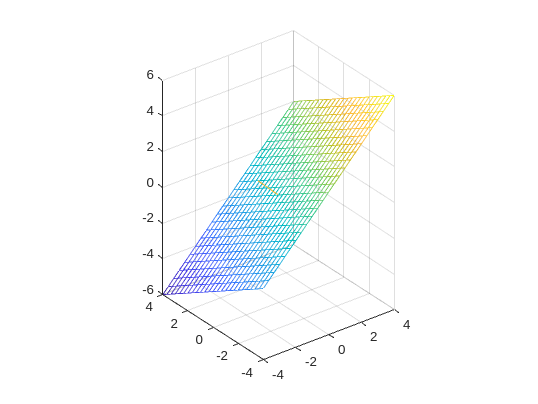

A=sym([1 0 1; 0 2 -1]'); n=null(A');
[x,y]=meshgrid(linspace(-4,4,25));
z=-(n(1)*x+n(2)*y)/n(3);
mesh(x,y,z);
hidden off; hold on; axis equal;
quiver3(0,0,0,n(1),n(2),n(3));

%view([n(1),n(2),n(3)])
[AZ,EL,rho]=cart2sph(n(1),n(2),n(3));
view(90+AZ*180/pi,EL*180/pi);

Error using view
Invalid input arguments.